# MATLAB Confidence Limit Sandbox

This is a demonstration of how confidence limits work.  We are using a large dataset to mimic a population.  (Warning, typos are legion.)

This code is written in MATLAB.  Don't worry if this is new to you.  You can try to follow the math and see if you can figure out what's going on.  The important take-home here is using a real dataset to demonstrate the theory of confidence limits.

Also this sheet is created using a "Live Script."  This is similar to the larger format of Mathcad where you can annotate your work.  It's acutally closer to working with a R "notebook" or Jupyter Notebook.  Resources like these are great ways to document your code to ensure that users [and hopefully, students] understand what is going on so they can repeat the demonstrated "experiments."

[Also, I appologize in advance since typos will be legion in these early drafts]

## Our Goals Here

What we want to do here is to take an *expected value* of a population, *E*(x), which for us will be the mean value of a sample, $\bar{x}$, which is a limited number of points extracted from a idealized population (or in the example we will use here... a huge dataset that can pretend to be our "population")

That's easy.  

Then what we want to do is calculate the wiggle room around our mean where we can expect our true population mean, $\mu_x$, (whcih we can't truely get in a realistic case) to sit.

or... 


$$\mu_x =\bar{x} \pm \Delta x$$


When speaking professionally, we call this the*** "confidence limit"*** (some also call it the "confidence interval")

Now we are never going to be 100% sure of being able to perfectly nail this wiggle room.  So we will have to establish a limit of certainty for what $\Delta x$ can capture.... for example a 95% confidence (which is often the typical level of confidence we use).  

From previous misadventures with the Central Limit Theorem, we understand that if we take a large number of estimates of a population's mean over and over then plot it, those results will form a normal distribution.  This is true even when our distrbutions are far from symetrical and away from the idealized bell curve.

## The Data Set

So to work this example, we will need a dataset that we can "pretend" to be a "population" for demonstration purposes.

Be warned, this is a BIG file (about 75MB) and the script may take a minute to extract the data from our servers.

The fields from this dataset are selected for a 3-D cube of temperature (39 vertical levels, 428 points in the east-west direction, and 614 point in the north-south direction) for a total of ~10 million points.  (Image of one layer of this dataset for air temperature is below)

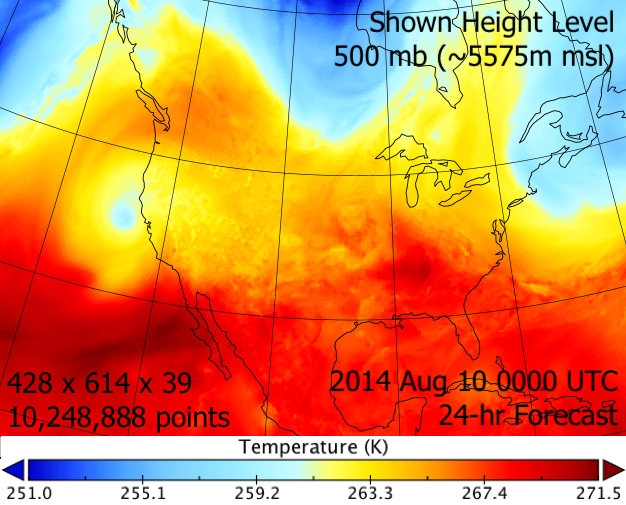

Once  again, we are pretending that this large dataset is an "faux population" for a hypothetical case, where we can only afford to extract a limited number of samples. 

## Cracking Open our Data

So let's start by cracking our big dataset and looking at our original dataset.  This dataset is kept on a "[THREDDS](http://kyrill.ias.sdsmt.edu:8080/thredds/catalog.html)" server at Mines and you can view the "inventory" of the file [here](http://kyrill.ias.sdsmt.edu:8080/thredds/ncss/CLASS_Examples/nam218_2014-08-10_00_F24.nc4/dataset.html).  [and yes, I DO have bigger files.. no really!]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
%  Data Access.  It's reading a netCDF file, a format for
%  storing large amounts of data.
%
% This is a netCDF File on our online repository at mines.

filename = 'http://kyrill.ias.sdsmt.edu:8080/thredds/dodsC/CLASS_Examples/nam218_2014-08-10_00_F24.nc4';    

% In this file is our 3-D temperature field... 

variable_name = 'TMP_218_ISBL';

% We read this data... 

data      = ncread(filename,variable_name);   % useful with "Big Data"

% We can also get some information on the data.

long_name = ncreadatt(filename,variable_name,'long_name');
units     = ncreadatt(filename,variable_name,'units');

n = numel(data);            % get the total # of data points

data = reshape(data,[1,n]); % force a 3D dataset into 1D

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


**Inspecting our "Population"**

Now let's take a look at our data with a histogram.  (Remember, here we are talking about the original population values which we normally woundn't have).

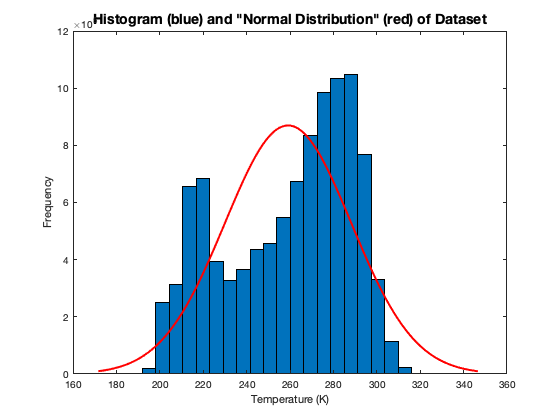

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
%  Plot a Histogram with a Normal Distribution Curve Fitted to it
figure('Name','Histogram of Full Dataset', ...
                 'Color','white'); % makes a white background, not grey
             
histfit(data,20);                  % generate histogram and curve fit
xlabel(strcat(long_name, ...       % we'll dock for no axis labels!
              ' (',      ...
              units,     ...
              ')'            ));                 
ylabel('Frequency');               % we'll still dock for no axis labels!
title('Histogram (blue) and "Normal Distribution" (red) of Dataset', ...
    'FontSize',14);                % titles are handy too...

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


So if you are using the "TMP_218_ISBL" dataset this should be a biomodal distribution with a tail going slightly negative (a bulk of the data is collected at high values).  As typical with multi-modal distributions "eyeballing" kurtosis even with a reference normal distributiuon line is a hard ball to call (it's acutally a little pointier with a kurtosis over 1 of we shave 3 of the formula, as is often the rule with kurtosis functions).

We can also get some basic statistics... 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% print our original faux population stats
%   The sprintf command is for "formatted" or controlled putput
%      the percent signs woudl read "%3d" for an 3-character-wide integer  
%      while %7.3f would be 7 minmum spaces ahead of a floating decimal
%      value with 3 places after the decimal point.
%

mu_d    = mean(data);  % our faux population mean
sigma_d = std(data);   % our faux popilation standard dev

% Let's plot our basic statistics  
%
% This looks terrible here as code but when 
% working with a live script "notebook" in Matlab the output will look 
% much better for you as a data consumer.

fprintf(['=============================================================\n', ...
         '         Number in "Populaton" = %d \n',                          ...
         '               population mean = %7.3f \n',                       ...
         ' population standard deviation = %7.3f \n',                       ...
         '           population skewness = %f \n',                          ...
         '         population kurtosis-3 = %f \n',                          ...
         '              population range = %7.3f to %7.3f \n',              ...
         '=============================================================\n'], ...
        n,                  ...
        mu_d,               ...
        sigma_d,            ...
        skewness(data),     ...
        kurtosis(data),     ...
        min(data),max(data) );

         Number in "Populaton" = 10248888 
               population mean = 259.124 
 population standard deviation =  29.147 
           population skewness = -0.435476 
         population kurtosis-3 = 1.951030 
              population range = 194.645 to 315.992 



%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

**Inspecting a "resonable" sample of our population.**

IOnce again, we normally don't have access to the above.  We can only surmise its characteristics from a sample.  So let's look at ***one*** of the possibilities of a sample that we realistically could extract.  

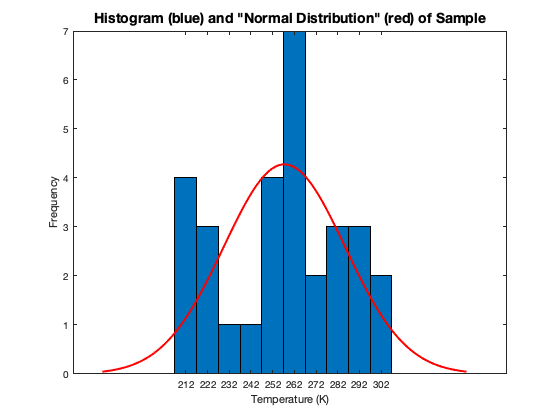

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
%  Plot a Histogram with a Normal Distribution Curve Fitted to it
figure('Name','Histogram of (30) Samples from our dataset', ...
              'Color','white'); % makes a white background, not grey
             
%  Pull a Subset from our "population"

n_sample_size       = 30; % the rule of thumb for samples

samples = randsample(data,n_sample_size);  % extract a random sample
                                           % without double counting
                                           
% note here that I am scaling back the number of "histogram bins" so
%  this is to accomodate a smaller sample size. This keeps the histogram
%  from having a "comb" look-n-feel!
             
histfit(samples,10); % generate histogram and curve fit
xlabel(strcat(long_name, ...          % remember the labels!
              ' (',      ...
              units,     ...
              ')'            ));                 
ylabel('Frequency');               % no really, we need them... 
title('Histogram (blue) and "Normal Distribution" (red) of Sample', ...
    'FontSize',14);                % and get us the titles too... 

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Each time this script is run, we should get different results.  But in theory, we should get a histogram that vaguely looks like or original data set most of the time.  That is going to the point of us doing this over and over 1000 times later in this example/exercize.

Note also that the more samples you use, the more likely you are to emulate the original histogram.

**Locking Down the Mean.**

Let's now get our mean value here.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Let's plot our basic statistics  
%
% This looks terrible here as code but when 
% working with a live script "notebook" in Matlab the output will look 
% much better for you as a data consumer.

fprintf(['=============================================================\n',  ...
         '    -- values in brackets are the population statistics --   \n',  ...
         '          Number in Sample = %d [%d]\n',                           ...
         '               sample mean = %7.3f [%7.3f]\n',                     ...
         ' sample standard deviation = %7.3f [%7.3f]\n',                     ...
         '           sample skewness = %f [%f]\n',                           ...
         '         sample kurtosis-3 = %f [%f] \n',                          ...
         '              sample range = %4.0f to %4.0f [%4.0f to %4.0f]\n',   ...
         '=============================================================\n'], ...
        n_sample_size,  n,        ...
        mean(samples),  mean(data),         ...
        std(samples), std(data),           ...
        skewness(samples), skewness(data),     ...
        kurtosis(samples),kurtosis(data),      ...
        min(samples),max(samples), min(data),max(data) );

    -- values in brackets are the population statistics --   
          Number in Sample = 30 [10248888]
               sample mean = 257.427 [259.124]
 sample standard deviation =  27.970 [ 29.147]
           sample skewness = -0.134261 [-0.435476]
         sample kurtosis-3 = 1.953463 [1.951030] 
              sample range =  212 to  305 [ 195 to  316]



%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

So obviously our sample's stats are not going to be exactly like the population's (and each time we go through this exercise, we'd get different values), all near the popuilation values but rarely hitting them on the bullseye.

This is why we are establishing a "confidence limit" (a $\Delta x$)  on our relationship, $\mu_x =\bar{x} \pm \Delta x$.

Let's guess as to what we are going to see in an ideal method to calculate $\Delta x$ based on what we can infer from our sample's stats from any one "roll of the dice" to get the sample's information.

- we should expand our guess's confidence range for large spreads in the data ($s_x$) 

- we should contract our guess's confidence range if we have more samples ($n$)

- we should expand our guess's confidence range if we increase our percent confidence [we'll call this $\left(1-\alpha \right)$ as we move forward]

So if we were to "doodle" our "equation-of-confidence" structure it should look something like this...

$\mu_x \simeq \bar{x} \pm \;\frac{f_1 \left(s_x \right)\;f_2 \left(1-\alpha \right)}{f_3 \left(n\right)}$.

$f_2 \left(1-\alpha \right)$ will be what we call our "inverse t-statistic" (more on that shortly) but let's look at the $f_1 \left(s_x \right)\;/f_3 \left(n\right)$.  We've addressed this with the Central Limit Theorem....

We found that the variance on the mean's standard deviation could be associated with the sample mean's sample deviation.

This can be expressed as a statistic called "the standard normal estimate."


$$\bar{z} \;\mathrm{or}\;z_{\overline{x} } =\frac{\bar{x} -\mu_x }{\sigma_x /\sqrt{n}}$$


That term on the bottom is trying to "normalize" the deviation of any sample mean from the population mean.  Here the standard deviation of a repeated collection of  $\overline{z}$'s from a populationfor should be around 1-ish and the mean of $\overline{z} \;$should hover around 0.

Now we have a problem here...  In a realisitc case we aren't going to have a popilation standard deviation.  We are going to have to "wing it" with the sample standard deviation.

We can do that too.  We call this statistic "the Student's-T" value.  


$$t=\frac{\overline{x} -\mu_x }{s_x /\sqrt{n}}$$


## But I digress...

This wasn't developed for pedagogical purposes.  Nor was the developer's name "Student." It was William Sealy Gosset, who worked for the Guiness Brewing Company.  Who had a limited number of... "barley"... samples to test for quality.  Because of "trade secrets," management at Guiness requested that he publish his work under a pseudonym.

Fortunately, even though you can't enjoy the concrete fruits of his labor until you are of legal age  [[university policy disclaimer]](https://www.sdsmt.edu/Campus-Life/Student-Health-and-Safety/Policies/Alcohol-and-Substance-Abuse-Consequences/).  The methodology was [published](https://www.york.ac.uk/depts/maths/histstat/student.pdf) for everyone who's been through calculus can enjoy.

## Exploring and Exploiting the Student's-T Distribution

if you were to take a dataset and repeately extact a huge number of t-statistics for a given value you would get a "*normal-ish"* distribution.  

*This is acutally shown at the bottom of this exercise.  *

The true formula isn't exactly the classic gaussian normal distribution curve and it varies based on the number of samples you use to create each value of *t.*

For this we need to leverage "The Degree of Freedom", often symbolized as *df* or $\nu$.   There is a great video demo on how degrees of freedom work [here](https://www.youtube.com/watch?v=rATNoxKg1yA).

Let's compare how the "t' probability density function (pdf) compares to the nomal distributiuon.

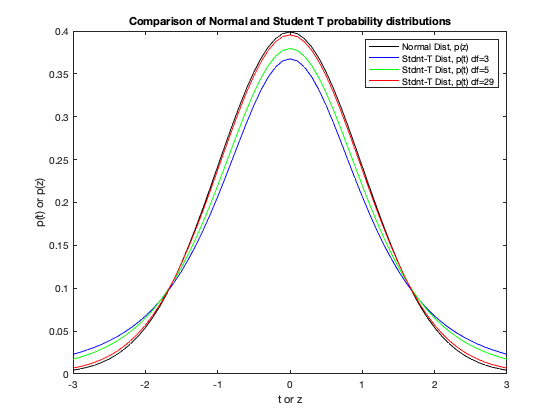

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Plotting Student-t distributions with a normal dist as a reference
%
% 
%

range_of_t_or_z = -3 : 0.1 : 3;

n_pdf    = normpdf(range_of_t_or_z);

t_pdf_03 = tpdf(range_of_t_or_z,  3);
t_pdf_05 = tpdf(range_of_t_or_z,  5);
t_pdf_29 = tpdf(range_of_t_or_z, 29);

figure('Name','Students-t and Normal Distributions', ...
                 'Color','white'); % makes a white background, not grey

plot(range_of_t_or_z, n_pdf,     'k', ... % blacK Line
     range_of_t_or_z, t_pdf_03,  'b', ...  % Blue Line
     range_of_t_or_z, t_pdf_05,  'g', ...  % Green Line
     range_of_t_or_z, t_pdf_29,  'r' );     % Red Line
title("Comparison of Normal and Student T probability distributions");
xlabel("t or z");                 
ylabel('p(t) or p(z)');      
legend('Normal Dist, p(z)', ...
       'Stdnt-T Dist, p(t) df=3',         ...
       'Stdnt-T Dist, p(t) df=5',         ...
       'Stdnt-T Dist, p(t) df=29');

     
 
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Examining the plot we see that the kurtosis is slightly below (i.e., it's flatter) that of the normal distributiion.  The curves become closer and closer to the normal distribution as you increase the degrees of freedom.

Now with that established we can now attack that last parameter, the "confidence" in getting our solution.

Let's go back to the formula of our T statistic.


$$t=\frac{\overline{x} -\mu_x }{s_x /\sqrt{n}}$$


If we apply some Algebra-Fu and try to solve for $\mu_x$ (recognize that we have a top and lower bound), we get this formula...


$$\begin{array}{l}
t=\frac{\bar{x} -\mu_x }{s_x /\sqrt{n}}\\
\bar{x} -\mu_x =\frac{s_x }{\sqrt{n}}\;t\\
\mu_x \simeq \bar{x} \pm \frac{s_x }{\sqrt{n}}\;t
\end{array}$$


look familiar?


$$\begin{array}{l}
\mu_x \simeq \bar{x} \pm \;\frac{f\left(s_x \right)\;f\left(1-\alpha \right)}{f\left(n\right)}\\
\mu_x \simeq \bar{x} \pm \;\frac{f\left(s_x \right)\;}{f\left(n\right)}f\left(1-\alpha \right)\simeq \bar{x} \pm \frac{s_x }{\sqrt{n}}\;t
\end{array}$$


We have $s_x$ and *n *covered*.   *So now all we have to do is get a number for *t* that represents $f\left(1-\alpha \right)$.  

Here's how we'll do this.  Let's say that we want to establish confidence wiggle room (confidence limits) so that we have a 95% chance of any one sample pull of estimating $\mu_x$ from that given sample using $\bar{x}$.

If you recall how probability works with respect to our distribution curves, we want to capure an area under this curve that covers 95% of the underlying area,

$P\left(t\right)=0\ldotp 95=\int_{t_{\textrm{low}} }^{t_{\textrm{high}} } p\left(t\right)\textrm{dt}$.

For us, we are going to be symetrical so we can rephrase our equation, integrating under the curve symetrically outward from the middle until we get a 95% area extracted.  Here, we are looking for a 95% probability so that's a 0.95 value of area that we're trying to capture.  Hence, our $\left(1-\alpha \right)$=0.95 This will exclude 5% of the area which is our "$\alpha$" of 0.05 so our t-values will hit symetrically on either side of our *t=*0 at  ${\pm t}_{\alpha /2}$.  This is sometimes called the "two-tailed *t*".


$$P\left(t\right)=0\ldotp 95=\int_{-t_{\alpha /2} }^{t_{\alpha /2} } p\left(t\right)\textrm{dt}$$


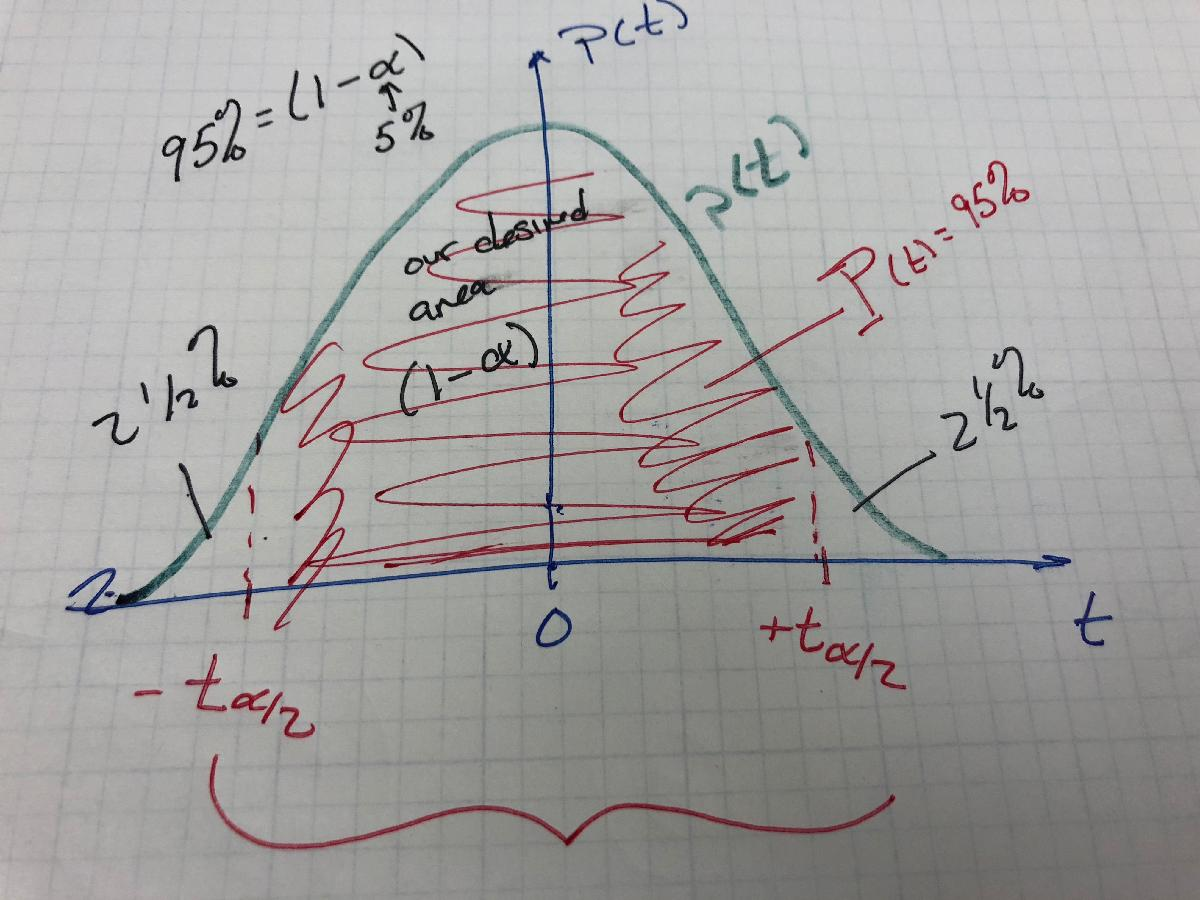

In the old days we did this with tables like from my old textbook one shown below...  

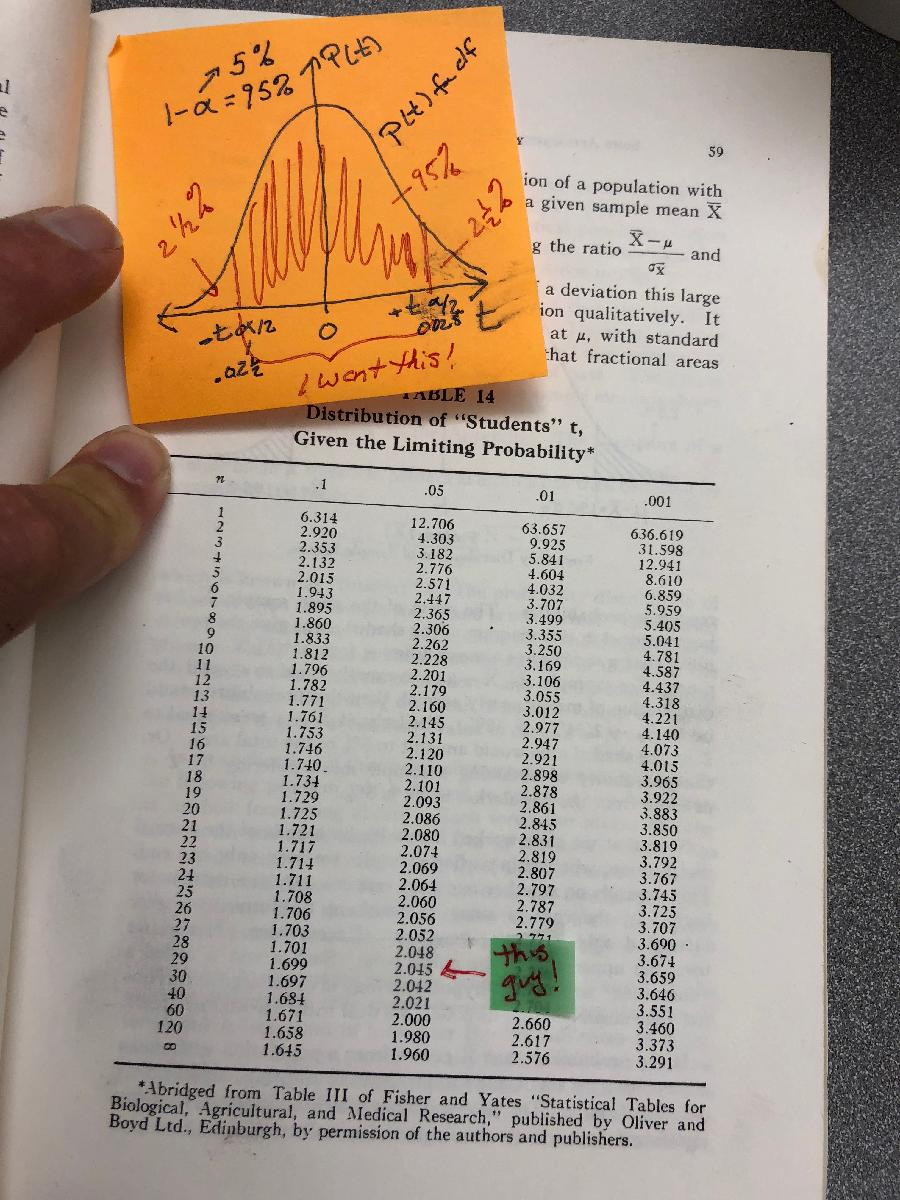

... so...  if we use a sample size of 30, our degree of freedom is 29 in this case. (The textbook uses "n" for degrees of freedom and that's along the far left column).  Along the top are our alphas for the above table shown.  Note that some textbooks use $\alpha /2$ at the top so look carefully at the documentation. So here our desired value is for $t_{\alpha /2}$ is 2.045 for that particular given degree of freedom.  This completes our calculation of confidence limits on our mean!


$$\mu_x \simeq \bar{x} \pm \frac{s_x }{\sqrt{n}}\;t_{\left(\alpha /2,\mathrm{df}\right)}$$


(Notice the role of $s_x /\sqrt{n}$, which is scaling $t_{\left(\alpha /2,\textrm{df}\right)}$ for the existing sample's natural spread and number of samples used).

## Calculating $t_{\left(\alpha /2,\textrm{df}\right)}$ the Modern Way. 

In the amazing futuristic 21st century, we rely more on software to calculate our t-statistics. As with the various textbook tables, users need to review documentation on how to make use of it for their particular package.  "Subtlly, all software calculating these values are different" but when used properly have the same results. 

In MATLAB, the [function](https://www.mathworks.com/help/stats/tinv.html) to do this is $\textrm{tinv}\left(\mathit{\mathbf{p}}=\left(1-\alpha /2\right),\textrm{df}=1-\mathit{\mathbf{n}}\right)$.

In Mathcad, the [function](http://support.ptc.com/help/mathcad/en/index.html#page/PTC_Mathcad_Help/students_t_distribution.html) to do this is $\textrm{qt}\left(\mathit{\mathbf{p}}=\left(1-\alpha /2\right),\textrm{df}=1-\mathit{\mathbf{n}}\right)\ldotp$

In R, the [function](https://www.rdocumentation.org/packages/stats/versions/3.5.1/topics/TDist) to do this is [also] $\textrm{qt}\left(\mathit{\mathbf{p}}=\left(1-\alpha /2\right),\textrm{df}=1-\mathit{\mathbf{n}}\right)\ldotp$

So in each of the above cases for a 95% confidence interval you need to enter in *p=0.975*

Excel has two ways to do this that I've found useful...

- [getting the correct t-value](https://support.office.com/en-us/article/t-inv-2t-function-ce72ea19-ec6c-4be7-bed2-b9baf2264f17) can be done with $\mathbf{T}\ldotp \mathbf{INV}\ldotp 2\mathbf{T}\left(1-\mathit{\mathbf{p}}=\alpha ,\textrm{df}=1-\mathit{\mathbf{n}}\right)$

- but it also can [calciulate all of the confidence interval](https://support.office.com/en-us/article/confidence-t-function-e8eca395-6c3a-4ba9-9003-79ccc61d3c53) with $\mathbf{CONFIDENCE}\ldotp \mathit{\mathbf{T}}\left(1-\mathit{\mathbf{p}}=\alpha ,{\mathit{\mathbf{s}}}_{\mathit{\mathbf{x}}} ,\mathit{\mathbf{n}}\right)$

- Note that both of these methods in Excel use the 

## So seriouisly... how good is it?

The code here is set for 

- n=30 samples.

- a $\left(1-\alpha \right)$ = 95% confidence of capturing the mean

- and we're going to loosly test our hypothesis with 1000 repeated tests where we extract our samples, calculate our sample mean and standard deviation and the confidence interval on each dive into our population.

To test this, we'll count when we capture the "faux" population mean within our confidence limit and when we're too high and to low.

We *should* have a result with about 95% confidence.  Sometimes we really hit the jackpot and the too-high and too-low are evenly split.

First, let's get out parameters that we only need to declare or calculate once. 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
%  Confidence Limit Parameters
%
%    User can change the sample size # of tests and percent confidence.
%

n_sample_size       = 30;
percent_confidence  = 95.0;

number_of_tests     = 1000;  % the bigger the number, the longer it takes

alpha               = 1 - percent_confidence/100.0;
degree_of_freedom   = n_sample_size-1;
test_number         = 1:number_of_tests;

t_statistic = tinv(1-alpha/2, degree_of_freedom); % get the t-stat.

fprintf(['=============================================================\n', ...
         '             Number in Samples = %d \n',   ...
         '      Desired Confidence Level = %f \n',   ...
         '                 Desired Alpha = %f \n',   ...
         '               Desired Alpha/2 = %f \n',   ...
         '                  t(%3.2f/2,%2d) = %f \n', ...
         '                                     \n',  ...
         '                Number in Tests = %d \n',  ...
         '=============================================================\n'], ...
           n_sample_size,  ...
           percent_confidence, ...
           alpha, ...
           alpha/2, ...
           alpha,degree_of_freedom,t_statistic, ...
           number_of_tests);

             Number in Samples = 30 
      Desired Confidence Level = 95.000000 
                 Desired Alpha = 0.050000 
               Desired Alpha/2 = 0.025000 
                  t(0.05/2,29) = 2.045230 
                                     
                Number in Tests = 1000 



%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Our next  step is to create the arrays into which we will place our answers for each of our individual tests.  



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Now let's set up some arrays for our next step using the zero function
%   to create a set of arrays filled with zeros
%
% So I'm creating a bunch of zero arrays with indicies 
%    from 1 to my number of tests
%

mean_archive = zeros([1,number_of_tests]); % we'll each test's sample mean here
stdv_archive = zeros([1,number_of_tests]); % we'll put the sample's standard deviation here.
conf_archive = zeros([1,number_of_tests]); % we'll put the confidence interval here.
hi_archive   = zeros([1,number_of_tests]); % top of the confidence envelope goes here
lo_archive   = zeros([1,number_of_tests]); % bottom of the confidence envelope goes here

t_archive    = zeros([1,number_of_tests]); % my t=(xbar-mu_d)/(stdev/sqrt(n_samples))

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

And now for a loop that goes through our requested number of tests to caclulate all of our scientific-adventure-violence!

Inside the loop we do the following

- Pull the samples using a function that keeps you from chosing any member of the population twice

- Calculate our various statistics.. 

- Do a too-hot vs too-cold vs just-right test.

- Print the results of the test... this is why this is a loooooonnnngggg document!

And when done we'll compile all the results and see overall how well we do.

So let's let'er rip!

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%

n_within  = 0;  %
n_outside = 0;  % counter of values outside of confidence limit

n_too_high = 0;  % counter of values outside of confidence limit
n_too_low  = 0;


%  Loop on i from 1 to number of tests.

for i = 1:number_of_tests

    samples = randsample(data,n_sample_size);  % extract a random sample
                                               % without double counting
  
    % calculate mean, standard dev and confidence interv. of sample
    x_bar = mean(samples);  
    s     = std(samples);
    conf  =  t_statistic * s / sqrt(n_sample_size);
    
    t     = (x_bar - mu_d) / (s / sqrt(n_sample_size));
    
    hi =   x_bar + conf;  % high limit to Conf of mean(x)
    lo =   x_bar - conf;  % low  limit to Conf of mean(x)

    % store key value for future use
    
    mean_archive(i) = x_bar;
    stdv_archive(i) = s;
    conf_archive(i) = conf;
    lo_archive(i)   = lo;
    hi_archive(i)   = hi;
    
    t_archive(i)    = t;


    % Checks to see if you are between the confidence limts.

    if ((lo < mu_d) && (mu_d < hi))  
        % "Sometimes You Get the Bear..."
        %     HUZZAH!  Your population mean is captured between the 
        %     confidence limits
        n_within = n_within + 1;
        fprintf('|| %4d mu=%7.3f ||  %7.3f <- %7.3f -> %7.3f \n', ...
                      i, mu_d, lo, x_bar, hi);
    else
        % "...Sometimes The Bear Gets You..."
        %     BAD THING!  Your population mean is not captured between the 
        %     confidence limits
        n_outside = n_outside + 1;
        if (mu_d < lo)  
           fprintf('<< %4d mu=%7.3f <<  %7.3f <- %7.3f -> %7.3f \n', ...
                        i, mu_d, lo, x_bar,hi);
           n_too_low = n_too_low + 1;
        end
        if (mu_d > hi)  
           fprintf('>> %4d mu=%7.3f >>  %7.3f <- %7.3f -> %7.3f \n', ...
                        i,mu_d,lo,x_bar,hi);
           n_too_high = n_too_high + 1;
        end
        
    end

end

||    1 mu=259.124 ||  245.231 <- 256.939 -> 268.647 
||    2 mu=259.124 ||  250.893 <- 261.029 -> 271.164 
||    3 mu=259.124 ||  250.450 <- 261.079 -> 271.707 
||    4 mu=259.124 ||  249.388 <- 262.198 -> 275.007 
||    5 mu=259.124 ||  240.202 <- 251.628 -> 263.055 
||    6 mu=259.124 ||  246.532 <- 256.670 -> 266.808 
||    7 mu=259.124 ||  257.630 <- 266.813 -> 275.996 
||    8 mu=259.124 ||  251.904 <- 262.846 -> 273.787 
||    9 mu=259.124 ||  253.180 <- 263.162 -> 273.143 
||   10 mu=259.124 ||  236.042 <- 248.103 -> 260.163 
||   11 mu=259.124 ||  250.937 <- 261.843 -> 272.749 
||   12 mu=259.124 ||  244.178 <- 255.314 -> 266.451 
||   13 mu=259.124 ||  251.969 <- 262.839 -> 273.708 
||   14 mu=259.124 ||  247.659 <- 258.786 -> 269.912 
||   15 mu=259.124 ||  253.614 <- 263.776 -> 273.937 
||   16 mu=259.124 ||  253.022 <- 264.264 -> 275.506 
||   17 mu=259.124 ||  248.633 <- 259.769 -> 270.905 
||   18 mu=259.124 ||  249.202 <- 260.032 -> 270.863 
||   19 mu=259.124 ||  252.9

>>   75 mu=259.124 >>  229.735 <- 242.114 -> 254.493 


||   76 mu=259.124 ||  247.037 <- 257.600 -> 268.164 
||   77 mu=259.124 ||  248.661 <- 258.929 -> 269.197 
||   78 mu=259.124 ||  251.203 <- 262.683 -> 274.162 
||   79 mu=259.124 ||  243.362 <- 255.618 -> 267.874 
||   80 mu=259.124 ||  246.232 <- 256.456 -> 266.679 
||   81 mu=259.124 ||  247.136 <- 257.608 -> 268.080 
||   82 mu=259.124 ||  245.229 <- 255.596 -> 265.963 
||   83 mu=259.124 ||  241.440 <- 252.703 -> 263.965 
||   84 mu=259.124 ||  244.706 <- 254.212 -> 263.718 
||   85 mu=259.124 ||  254.610 <- 265.669 -> 276.728 
||   86 mu=259.124 ||  247.456 <- 258.997 -> 270.538 
||   87 mu=259.124 ||  240.446 <- 252.429 -> 264.412 
||   88 mu=259.124 ||  242.595 <- 254.732 -> 266.870 
||   89 mu=259.124 ||  237.731 <- 249.217 -> 260.704 
||   90 mu=259.124 ||  248.738 <- 260.337 -> 271.936 
||   91 mu=259.124 ||  253.628 <- 264.362 -> 275.097 
||   92 mu=259.124 ||  250.520 <- 261.164 -> 271.808 
||   93 mu=259.124 ||  247.471 <- 258.190 -> 268.910 
||   94 mu=259.124 ||  254.5

<<  104 mu=259.124 <<  259.414 <- 268.798 -> 278.183 


||  105 mu=259.124 ||  251.193 <- 262.419 -> 273.644 
||  106 mu=259.124 ||  246.949 <- 259.005 -> 271.062 
||  107 mu=259.124 ||  251.418 <- 261.839 -> 272.260 
||  108 mu=259.124 ||  245.616 <- 257.268 -> 268.920 
||  109 mu=259.124 ||  242.500 <- 254.838 -> 267.176 
||  110 mu=259.124 ||  256.199 <- 266.524 -> 276.850 
||  111 mu=259.124 ||  243.011 <- 255.139 -> 267.266 
||  112 mu=259.124 ||  245.700 <- 256.495 -> 267.291 
||  113 mu=259.124 ||  237.892 <- 248.964 -> 260.036 
||  114 mu=259.124 ||  246.555 <- 257.510 -> 268.466 
||  115 mu=259.124 ||  250.150 <- 261.226 -> 272.301 
||  116 mu=259.124 ||  237.414 <- 249.136 -> 260.859 
||  117 mu=259.124 ||  251.973 <- 261.392 -> 270.810 
||  118 mu=259.124 ||  241.323 <- 254.200 -> 267.078 
||  119 mu=259.124 ||  246.507 <- 258.063 -> 269.619 
||  120 mu=259.124 ||  248.204 <- 259.044 -> 269.883 


<<  121 mu=259.124 <<  260.946 <- 269.290 -> 277.635 


||  122 mu=259.124 ||  254.633 <- 264.532 -> 274.432 
||  123 mu=259.124 ||  243.932 <- 254.800 -> 265.667 
||  124 mu=259.124 ||  248.902 <- 260.137 -> 271.372 
||  125 mu=259.124 ||  253.090 <- 264.628 -> 276.167 
||  126 mu=259.124 ||  253.264 <- 264.303 -> 275.343 
||  127 mu=259.124 ||  244.600 <- 254.019 -> 263.437 
||  128 mu=259.124 ||  241.342 <- 250.946 -> 260.550 
||  129 mu=259.124 ||  247.757 <- 258.287 -> 268.817 
||  130 mu=259.124 ||  255.489 <- 264.651 -> 273.812 
||  131 mu=259.124 ||  248.258 <- 260.107 -> 271.956 
||  132 mu=259.124 ||  245.602 <- 255.799 -> 265.997 
||  133 mu=259.124 ||  245.521 <- 256.779 -> 268.037 
||  134 mu=259.124 ||  241.302 <- 253.095 -> 264.889 
||  135 mu=259.124 ||  243.137 <- 254.676 -> 266.216 
||  136 mu=259.124 ||  249.992 <- 259.630 -> 269.268 
||  137 mu=259.124 ||  247.606 <- 258.712 -> 269.817 
||  138 mu=259.124 ||  240.726 <- 252.127 -> 263.528 
||  139 mu=259.124 ||  250.102 <- 260.324 -> 270.546 
||  140 mu=259.124 ||  252.3

<<  152 mu=259.124 <<  260.671 <- 271.171 -> 281.671 


||  153 mu=259.124 ||  241.265 <- 252.601 -> 263.937 
||  154 mu=259.124 ||  252.279 <- 262.383 -> 272.487 


<<  155 mu=259.124 <<  260.736 <- 270.844 -> 280.952 


||  156 mu=259.124 ||  257.007 <- 265.551 -> 274.095 
||  157 mu=259.124 ||  246.267 <- 257.837 -> 269.407 
||  158 mu=259.124 ||  241.841 <- 254.374 -> 266.907 
||  159 mu=259.124 ||  247.214 <- 257.792 -> 268.371 
||  160 mu=259.124 ||  246.771 <- 259.018 -> 271.266 
||  161 mu=259.124 ||  247.129 <- 258.417 -> 269.704 
||  162 mu=259.124 ||  242.512 <- 254.551 -> 266.589 
||  163 mu=259.124 ||  244.613 <- 256.003 -> 267.393 
||  164 mu=259.124 ||  246.215 <- 257.526 -> 268.838 
||  165 mu=259.124 ||  250.446 <- 262.111 -> 273.777 
||  166 mu=259.124 ||  248.629 <- 260.146 -> 271.664 
||  167 mu=259.124 ||  248.494 <- 259.323 -> 270.151 
||  168 mu=259.124 ||  246.544 <- 256.317 -> 266.091 
||  169 mu=259.124 ||  242.961 <- 255.645 -> 268.328 
||  170 mu=259.124 ||  245.511 <- 256.087 -> 266.663 
||  171 mu=259.124 ||  248.238 <- 260.160 -> 272.083 
||  172 mu=259.124 ||  251.321 <- 260.816 -> 270.311 


<<  173 mu=259.124 <<  260.332 <- 269.852 -> 279.372 


||  174 mu=259.124 ||  240.700 <- 252.750 -> 264.799 
||  175 mu=259.124 ||  247.183 <- 258.113 -> 269.043 
||  176 mu=259.124 ||  245.176 <- 256.459 -> 267.742 
||  177 mu=259.124 ||  253.432 <- 264.165 -> 274.897 
||  178 mu=259.124 ||  244.833 <- 257.513 -> 270.194 
||  179 mu=259.124 ||  256.962 <- 266.974 -> 276.985 
||  180 mu=259.124 ||  254.124 <- 264.885 -> 275.646 
||  181 mu=259.124 ||  247.663 <- 257.699 -> 267.734 
||  182 mu=259.124 ||  249.820 <- 260.284 -> 270.748 
||  183 mu=259.124 ||  251.000 <- 261.835 -> 272.670 
||  184 mu=259.124 ||  243.998 <- 254.440 -> 264.883 
||  185 mu=259.124 ||  243.635 <- 256.598 -> 269.561 
||  186 mu=259.124 ||  254.214 <- 264.160 -> 274.105 
||  187 mu=259.124 ||  256.161 <- 265.019 -> 273.876 
||  188 mu=259.124 ||  248.264 <- 260.759 -> 273.254 
||  189 mu=259.124 ||  251.556 <- 261.685 -> 271.814 
||  190 mu=259.124 ||  254.334 <- 264.950 -> 275.566 
||  191 mu=259.124 ||  249.471 <- 260.058 -> 270.646 
||  192 mu=259.124 ||  238.8

>>  199 mu=259.124 >>  235.014 <- 246.910 -> 258.805 


||  200 mu=259.124 ||  250.837 <- 261.735 -> 272.634 
||  201 mu=259.124 ||  240.118 <- 252.478 -> 264.838 
||  202 mu=259.124 ||  245.378 <- 257.247 -> 269.117 
||  203 mu=259.124 ||  258.244 <- 267.909 -> 277.573 
||  204 mu=259.124 ||  255.870 <- 266.555 -> 277.241 
||  205 mu=259.124 ||  245.018 <- 256.702 -> 268.385 
||  206 mu=259.124 ||  246.226 <- 255.342 -> 264.458 
||  207 mu=259.124 ||  249.833 <- 259.388 -> 268.943 
||  208 mu=259.124 ||  246.158 <- 256.997 -> 267.836 
||  209 mu=259.124 ||  244.851 <- 256.380 -> 267.910 
||  210 mu=259.124 ||  246.719 <- 255.446 -> 264.174 
||  211 mu=259.124 ||  244.055 <- 255.171 -> 266.288 
||  212 mu=259.124 ||  248.127 <- 259.359 -> 270.590 
||  213 mu=259.124 ||  251.443 <- 262.937 -> 274.432 
||  214 mu=259.124 ||  250.275 <- 261.951 -> 273.628 
||  215 mu=259.124 ||  251.625 <- 262.768 -> 273.911 


<<  216 mu=259.124 <<  259.789 <- 269.201 -> 278.614 


||  217 mu=259.124 ||  249.498 <- 260.092 -> 270.686 
||  218 mu=259.124 ||  241.724 <- 254.265 -> 266.806 
||  219 mu=259.124 ||  246.756 <- 258.371 -> 269.986 
||  220 mu=259.124 ||  256.287 <- 265.751 -> 275.214 
||  221 mu=259.124 ||  245.536 <- 257.267 -> 268.999 
||  222 mu=259.124 ||  244.653 <- 256.638 -> 268.623 
||  223 mu=259.124 ||  258.332 <- 268.645 -> 278.958 
||  224 mu=259.124 ||  245.916 <- 257.133 -> 268.350 
||  225 mu=259.124 ||  238.984 <- 252.205 -> 265.426 
||  226 mu=259.124 ||  255.800 <- 266.369 -> 276.939 
||  227 mu=259.124 ||  246.073 <- 257.126 -> 268.179 
||  228 mu=259.124 ||  249.211 <- 259.868 -> 270.525 
||  229 mu=259.124 ||  245.916 <- 256.225 -> 266.534 
||  230 mu=259.124 ||  245.125 <- 256.887 -> 268.649 
||  231 mu=259.124 ||  250.858 <- 261.088 -> 271.319 
||  232 mu=259.124 ||  251.176 <- 262.338 -> 273.499 
||  233 mu=259.124 ||  241.917 <- 252.387 -> 262.858 
||  234 mu=259.124 ||  239.953 <- 251.205 -> 262.456 
||  235 mu=259.124 ||  251.0

<<  239 mu=259.124 <<  259.166 <- 269.464 -> 279.761 


||  240 mu=259.124 ||  247.376 <- 258.823 -> 270.270 
||  241 mu=259.124 ||  244.483 <- 256.910 -> 269.338 
||  242 mu=259.124 ||  250.794 <- 262.075 -> 273.356 
||  243 mu=259.124 ||  254.748 <- 264.672 -> 274.596 
||  244 mu=259.124 ||  249.124 <- 259.332 -> 269.541 
||  245 mu=259.124 ||  245.095 <- 257.689 -> 270.282 
||  246 mu=259.124 ||  248.581 <- 257.596 -> 266.611 
||  247 mu=259.124 ||  244.186 <- 254.601 -> 265.015 
||  248 mu=259.124 ||  242.411 <- 253.068 -> 263.726 
||  249 mu=259.124 ||  250.846 <- 261.905 -> 272.964 


>>  250 mu=259.124 >>  235.266 <- 246.661 -> 258.056 


||  251 mu=259.124 ||  253.539 <- 263.447 -> 273.355 
||  252 mu=259.124 ||  241.945 <- 254.518 -> 267.091 
||  253 mu=259.124 ||  250.810 <- 261.045 -> 271.280 
||  254 mu=259.124 ||  252.830 <- 262.122 -> 271.415 
||  255 mu=259.124 ||  255.454 <- 266.252 -> 277.050 
||  256 mu=259.124 ||  254.467 <- 263.487 -> 272.507 
||  257 mu=259.124 ||  240.113 <- 252.041 -> 263.970 
||  258 mu=259.124 ||  257.807 <- 267.690 -> 277.573 
||  259 mu=259.124 ||  246.170 <- 257.484 -> 268.797 


<<  260 mu=259.124 <<  260.357 <- 268.772 -> 277.187 


||  261 mu=259.124 ||  247.735 <- 257.559 -> 267.382 
||  262 mu=259.124 ||  253.031 <- 263.003 -> 272.974 
||  263 mu=259.124 ||  249.362 <- 259.811 -> 270.260 
||  264 mu=259.124 ||  239.067 <- 250.449 -> 261.831 
||  265 mu=259.124 ||  246.858 <- 257.125 -> 267.393 
||  266 mu=259.124 ||  253.401 <- 263.468 -> 273.535 
||  267 mu=259.124 ||  257.785 <- 266.608 -> 275.430 
||  268 mu=259.124 ||  248.296 <- 260.000 -> 271.705 
||  269 mu=259.124 ||  253.917 <- 263.857 -> 273.797 
||  270 mu=259.124 ||  249.887 <- 260.800 -> 271.712 
||  271 mu=259.124 ||  251.442 <- 262.800 -> 274.157 
||  272 mu=259.124 ||  250.305 <- 261.399 -> 272.494 
||  273 mu=259.124 ||  248.897 <- 258.899 -> 268.901 
||  274 mu=259.124 ||  245.385 <- 256.441 -> 267.496 
||  275 mu=259.124 ||  257.552 <- 267.281 -> 277.011 
||  276 mu=259.124 ||  237.349 <- 248.662 -> 259.974 
||  277 mu=259.124 ||  253.705 <- 263.911 -> 274.117 
||  278 mu=259.124 ||  255.514 <- 265.126 -> 274.737 
||  279 mu=259.124 ||  239.1

<<  289 mu=259.124 <<  262.198 <- 270.350 -> 278.502 


||  290 mu=259.124 ||  247.235 <- 258.186 -> 269.137 
||  291 mu=259.124 ||  247.317 <- 257.997 -> 268.676 
||  292 mu=259.124 ||  242.569 <- 253.734 -> 264.899 
||  293 mu=259.124 ||  244.468 <- 255.468 -> 266.468 
||  294 mu=259.124 ||  256.468 <- 264.902 -> 273.337 
||  295 mu=259.124 ||  248.199 <- 259.699 -> 271.198 
||  296 mu=259.124 ||  249.855 <- 261.175 -> 272.495 
||  297 mu=259.124 ||  248.252 <- 259.153 -> 270.054 
||  298 mu=259.124 ||  256.598 <- 268.053 -> 279.509 
||  299 mu=259.124 ||  246.868 <- 256.882 -> 266.895 
||  300 mu=259.124 ||  253.738 <- 265.207 -> 276.676 
||  301 mu=259.124 ||  245.167 <- 255.266 -> 265.365 
||  302 mu=259.124 ||  250.044 <- 261.456 -> 272.868 
||  303 mu=259.124 ||  245.804 <- 256.798 -> 267.792 
||  304 mu=259.124 ||  247.606 <- 259.629 -> 271.652 
||  305 mu=259.124 ||  245.046 <- 256.423 -> 267.800 
||  306 mu=259.124 ||  252.840 <- 263.060 -> 273.281 
||  307 mu=259.124 ||  250.988 <- 261.553 -> 272.119 
||  308 mu=259.124 ||  252.9

<<  325 mu=259.124 <<  263.304 <- 272.310 -> 281.316 


||  326 mu=259.124 ||  249.395 <- 260.232 -> 271.069 
||  327 mu=259.124 ||  245.525 <- 256.930 -> 268.335 
||  328 mu=259.124 ||  254.940 <- 264.770 -> 274.601 
||  329 mu=259.124 ||  252.504 <- 263.755 -> 275.007 
||  330 mu=259.124 ||  249.651 <- 259.933 -> 270.215 
||  331 mu=259.124 ||  255.246 <- 265.141 -> 275.037 
||  332 mu=259.124 ||  240.462 <- 252.015 -> 263.567 
||  333 mu=259.124 ||  237.756 <- 250.051 -> 262.345 
||  334 mu=259.124 ||  240.611 <- 251.179 -> 261.746 
||  335 mu=259.124 ||  240.784 <- 252.637 -> 264.491 
||  336 mu=259.124 ||  248.421 <- 261.293 -> 274.165 


<<  337 mu=259.124 <<  264.319 <- 272.485 -> 280.651 


||  338 mu=259.124 ||  252.685 <- 263.334 -> 273.983 
||  339 mu=259.124 ||  252.680 <- 264.067 -> 275.453 
||  340 mu=259.124 ||  248.952 <- 258.436 -> 267.921 
||  341 mu=259.124 ||  242.842 <- 254.251 -> 265.660 
||  342 mu=259.124 ||  258.697 <- 267.952 -> 277.206 
||  343 mu=259.124 ||  246.457 <- 257.696 -> 268.935 
||  344 mu=259.124 ||  241.080 <- 252.535 -> 263.991 
||  345 mu=259.124 ||  245.968 <- 257.463 -> 268.958 
||  346 mu=259.124 ||  248.640 <- 259.057 -> 269.474 
||  347 mu=259.124 ||  248.183 <- 259.674 -> 271.165 
||  348 mu=259.124 ||  242.568 <- 252.511 -> 262.454 
||  349 mu=259.124 ||  242.191 <- 253.944 -> 265.698 
||  350 mu=259.124 ||  242.234 <- 253.690 -> 265.147 
||  351 mu=259.124 ||  247.889 <- 259.885 -> 271.882 
||  352 mu=259.124 ||  238.179 <- 250.147 -> 262.116 
||  353 mu=259.124 ||  251.178 <- 261.212 -> 271.247 
||  354 mu=259.124 ||  242.916 <- 254.229 -> 265.541 
||  355 mu=259.124 ||  246.680 <- 256.253 -> 265.826 
||  356 mu=259.124 ||  247.0

<<  446 mu=259.124 <<  260.641 <- 269.251 -> 277.861 


||  447 mu=259.124 ||  244.787 <- 255.452 -> 266.117 
||  448 mu=259.124 ||  245.669 <- 256.885 -> 268.102 
||  449 mu=259.124 ||  246.792 <- 259.545 -> 272.299 
||  450 mu=259.124 ||  254.944 <- 266.331 -> 277.717 
||  451 mu=259.124 ||  250.085 <- 260.935 -> 271.786 
||  452 mu=259.124 ||  249.609 <- 261.119 -> 272.629 
||  453 mu=259.124 ||  252.903 <- 262.738 -> 272.574 
||  454 mu=259.124 ||  255.562 <- 264.990 -> 274.418 
||  455 mu=259.124 ||  249.734 <- 260.495 -> 271.256 
||  456 mu=259.124 ||  245.293 <- 255.932 -> 266.570 
||  457 mu=259.124 ||  252.822 <- 262.835 -> 272.848 
||  458 mu=259.124 ||  244.117 <- 253.842 -> 263.567 
||  459 mu=259.124 ||  250.015 <- 261.367 -> 272.719 
||  460 mu=259.124 ||  244.803 <- 256.070 -> 267.336 
||  461 mu=259.124 ||  246.759 <- 258.091 -> 269.424 
||  462 mu=259.124 ||  250.399 <- 261.885 -> 273.372 
||  463 mu=259.124 ||  239.643 <- 252.495 -> 265.347 
||  464 mu=259.124 ||  252.407 <- 262.958 -> 273.509 


<<  465 mu=259.124 <<  259.419 <- 269.592 -> 279.765 


||  466 mu=259.124 ||  247.857 <- 259.711 -> 271.566 
||  467 mu=259.124 ||  242.262 <- 253.916 -> 265.570 
||  468 mu=259.124 ||  258.083 <- 267.769 -> 277.455 
||  469 mu=259.124 ||  239.225 <- 250.619 -> 262.013 
||  470 mu=259.124 ||  242.299 <- 253.572 -> 264.845 
||  471 mu=259.124 ||  247.506 <- 258.355 -> 269.205 
||  472 mu=259.124 ||  245.172 <- 256.434 -> 267.696 
||  473 mu=259.124 ||  243.566 <- 254.800 -> 266.033 
||  474 mu=259.124 ||  255.967 <- 265.503 -> 275.038 
||  475 mu=259.124 ||  249.373 <- 259.238 -> 269.102 
||  476 mu=259.124 ||  252.294 <- 262.594 -> 272.895 
||  477 mu=259.124 ||  248.782 <- 258.767 -> 268.752 
||  478 mu=259.124 ||  250.759 <- 262.764 -> 274.769 
||  479 mu=259.124 ||  246.998 <- 256.691 -> 266.385 
||  480 mu=259.124 ||  249.261 <- 258.915 -> 268.570 
||  481 mu=259.124 ||  253.770 <- 262.275 -> 270.781 
||  482 mu=259.124 ||  254.861 <- 265.247 -> 275.632 
||  483 mu=259.124 ||  255.681 <- 266.707 -> 277.732 
||  484 mu=259.124 ||  248.5

<<  509 mu=259.124 <<  262.411 <- 271.556 -> 280.701 


||  510 mu=259.124 ||  254.652 <- 263.274 -> 271.897 
||  511 mu=259.124 ||  249.610 <- 260.015 -> 270.420 
||  512 mu=259.124 ||  244.547 <- 256.140 -> 267.733 
||  513 mu=259.124 ||  237.269 <- 248.720 -> 260.170 
||  514 mu=259.124 ||  246.529 <- 257.059 -> 267.588 
||  515 mu=259.124 ||  245.269 <- 256.973 -> 268.677 
||  516 mu=259.124 ||  245.094 <- 256.487 -> 267.879 
||  517 mu=259.124 ||  256.143 <- 265.593 -> 275.043 
||  518 mu=259.124 ||  240.444 <- 252.796 -> 265.148 
||  519 mu=259.124 ||  248.918 <- 260.106 -> 271.294 
||  520 mu=259.124 ||  235.150 <- 247.616 -> 260.081 
||  521 mu=259.124 ||  238.592 <- 250.626 -> 262.661 
||  522 mu=259.124 ||  243.106 <- 254.126 -> 265.146 
||  523 mu=259.124 ||  244.610 <- 257.068 -> 269.526 
||  524 mu=259.124 ||  244.157 <- 254.724 -> 265.290 
||  525 mu=259.124 ||  245.450 <- 256.727 -> 268.005 
||  526 mu=259.124 ||  250.851 <- 261.502 -> 272.152 
||  527 mu=259.124 ||  243.608 <- 254.613 -> 265.618 
||  528 mu=259.124 ||  253.7

<<  537 mu=259.124 <<  262.079 <- 270.706 -> 279.333 


||  538 mu=259.124 ||  246.859 <- 257.943 -> 269.026 
||  539 mu=259.124 ||  244.182 <- 255.969 -> 267.756 
||  540 mu=259.124 ||  251.558 <- 262.391 -> 273.224 
||  541 mu=259.124 ||  247.064 <- 258.130 -> 269.196 
||  542 mu=259.124 ||  243.699 <- 255.713 -> 267.727 
||  543 mu=259.124 ||  244.059 <- 255.160 -> 266.262 
||  544 mu=259.124 ||  255.719 <- 266.841 -> 277.964 
||  545 mu=259.124 ||  245.556 <- 256.819 -> 268.081 
||  546 mu=259.124 ||  246.777 <- 258.547 -> 270.317 
||  547 mu=259.124 ||  255.483 <- 266.509 -> 277.535 
||  548 mu=259.124 ||  252.300 <- 263.386 -> 274.471 
||  549 mu=259.124 ||  253.997 <- 263.688 -> 273.378 
||  550 mu=259.124 ||  244.014 <- 258.159 -> 272.303 
||  551 mu=259.124 ||  249.849 <- 260.955 -> 272.061 
||  552 mu=259.124 ||  250.996 <- 259.647 -> 268.298 
||  553 mu=259.124 ||  246.602 <- 258.675 -> 270.747 
||  554 mu=259.124 ||  244.259 <- 256.032 -> 267.805 
||  555 mu=259.124 ||  243.835 <- 255.241 -> 266.647 
||  556 mu=259.124 ||  258.0

<<  589 mu=259.124 <<  259.931 <- 268.838 -> 277.744 


||  590 mu=259.124 ||  257.408 <- 265.875 -> 274.342 
||  591 mu=259.124 ||  244.271 <- 254.450 -> 264.629 
||  592 mu=259.124 ||  244.630 <- 256.591 -> 268.553 


<<  593 mu=259.124 <<  260.108 <- 269.104 -> 278.100 


||  594 mu=259.124 ||  249.816 <- 263.084 -> 276.352 
||  595 mu=259.124 ||  251.798 <- 261.339 -> 270.879 
||  596 mu=259.124 ||  247.509 <- 259.201 -> 270.892 
||  597 mu=259.124 ||  240.517 <- 251.129 -> 261.742 
||  598 mu=259.124 ||  253.744 <- 264.157 -> 274.569 
||  599 mu=259.124 ||  250.783 <- 260.720 -> 270.657 
||  600 mu=259.124 ||  242.565 <- 254.858 -> 267.152 
||  601 mu=259.124 ||  248.896 <- 260.007 -> 271.118 
||  602 mu=259.124 ||  236.257 <- 247.767 -> 259.277 
||  603 mu=259.124 ||  253.622 <- 263.932 -> 274.241 


>>  604 mu=259.124 >>  236.742 <- 247.007 -> 257.272 


<<  605 mu=259.124 <<  260.676 <- 268.651 -> 276.625 


||  606 mu=259.124 ||  255.235 <- 264.725 -> 274.214 
||  607 mu=259.124 ||  248.695 <- 259.680 -> 270.666 


>>  608 mu=259.124 >>  233.591 <- 245.308 -> 257.024 


||  609 mu=259.124 ||  251.857 <- 262.066 -> 272.276 


<<  610 mu=259.124 <<  260.653 <- 268.177 -> 275.700 


||  611 mu=259.124 ||  250.385 <- 260.575 -> 270.765 
||  612 mu=259.124 ||  243.613 <- 254.908 -> 266.203 
||  613 mu=259.124 ||  255.077 <- 263.961 -> 272.846 
||  614 mu=259.124 ||  253.466 <- 264.142 -> 274.818 
||  615 mu=259.124 ||  258.422 <- 270.469 -> 282.516 
||  616 mu=259.124 ||  252.424 <- 262.411 -> 272.399 
||  617 mu=259.124 ||  254.203 <- 265.223 -> 276.242 
||  618 mu=259.124 ||  244.716 <- 256.669 -> 268.622 
||  619 mu=259.124 ||  251.507 <- 261.718 -> 271.929 
||  620 mu=259.124 ||  249.388 <- 258.638 -> 267.889 
||  621 mu=259.124 ||  248.396 <- 259.808 -> 271.221 
||  622 mu=259.124 ||  253.259 <- 262.676 -> 272.093 
||  623 mu=259.124 ||  248.257 <- 259.006 -> 269.755 
||  624 mu=259.124 ||  250.298 <- 260.618 -> 270.938 
||  625 mu=259.124 ||  244.184 <- 255.733 -> 267.283 
||  626 mu=259.124 ||  254.910 <- 266.575 -> 278.240 
||  627 mu=259.124 ||  251.412 <- 262.089 -> 272.766 
||  628 mu=259.124 ||  254.428 <- 264.648 -> 274.868 
||  629 mu=259.124 ||  243.9

<<  644 mu=259.124 <<  261.728 <- 271.547 -> 281.366 


||  645 mu=259.124 ||  244.836 <- 255.670 -> 266.505 
||  646 mu=259.124 ||  258.246 <- 268.650 -> 279.054 
||  647 mu=259.124 ||  252.042 <- 263.162 -> 274.281 
||  648 mu=259.124 ||  253.001 <- 264.258 -> 275.516 
||  649 mu=259.124 ||  248.762 <- 259.741 -> 270.721 
||  650 mu=259.124 ||  258.496 <- 268.657 -> 278.818 
||  651 mu=259.124 ||  256.358 <- 265.863 -> 275.368 


<<  652 mu=259.124 <<  259.621 <- 268.538 -> 277.454 


||  653 mu=259.124 ||  250.689 <- 259.924 -> 269.158 
||  654 mu=259.124 ||  252.992 <- 264.486 -> 275.980 
||  655 mu=259.124 ||  254.921 <- 265.249 -> 275.577 
||  656 mu=259.124 ||  249.934 <- 259.282 -> 268.631 
||  657 mu=259.124 ||  245.955 <- 256.493 -> 267.031 
||  658 mu=259.124 ||  246.269 <- 255.900 -> 265.531 
||  659 mu=259.124 ||  245.391 <- 257.060 -> 268.729 
||  660 mu=259.124 ||  249.971 <- 262.003 -> 274.035 
||  661 mu=259.124 ||  256.182 <- 264.466 -> 272.750 
||  662 mu=259.124 ||  252.437 <- 264.093 -> 275.749 
||  663 mu=259.124 ||  254.539 <- 265.254 -> 275.970 
||  664 mu=259.124 ||  240.915 <- 252.798 -> 264.682 
||  665 mu=259.124 ||  242.352 <- 253.158 -> 263.963 
||  666 mu=259.124 ||  241.717 <- 252.744 -> 263.771 
||  667 mu=259.124 ||  250.433 <- 260.513 -> 270.594 
||  668 mu=259.124 ||  253.505 <- 264.473 -> 275.440 
||  669 mu=259.124 ||  244.893 <- 256.088 -> 267.283 
||  670 mu=259.124 ||  253.816 <- 265.008 -> 276.199 
||  671 mu=259.124 ||  246.8

<<  675 mu=259.124 <<  260.326 <- 269.222 -> 278.118 


||  676 mu=259.124 ||  243.237 <- 254.582 -> 265.927 


>>  677 mu=259.124 >>  233.889 <- 244.050 -> 254.210 


||  678 mu=259.124 ||  238.825 <- 249.569 -> 260.312 
||  679 mu=259.124 ||  250.950 <- 262.839 -> 274.728 


>>  680 mu=259.124 >>  234.731 <- 245.515 -> 256.300 


||  681 mu=259.124 ||  245.297 <- 255.586 -> 265.874 
||  682 mu=259.124 ||  238.895 <- 251.525 -> 264.155 


>>  683 mu=259.124 >>  240.034 <- 249.496 -> 258.957 


||  684 mu=259.124 ||  249.169 <- 261.278 -> 273.387 
||  685 mu=259.124 ||  241.945 <- 252.975 -> 264.006 
||  686 mu=259.124 ||  244.538 <- 256.280 -> 268.022 
||  687 mu=259.124 ||  240.036 <- 251.020 -> 262.005 
||  688 mu=259.124 ||  252.633 <- 264.435 -> 276.238 
||  689 mu=259.124 ||  248.283 <- 260.514 -> 272.744 


<<  690 mu=259.124 <<  259.367 <- 269.446 -> 279.525 


||  691 mu=259.124 ||  243.052 <- 253.540 -> 264.028 
||  692 mu=259.124 ||  247.576 <- 260.008 -> 272.439 
||  693 mu=259.124 ||  258.355 <- 267.308 -> 276.261 
||  694 mu=259.124 ||  241.643 <- 252.907 -> 264.170 
||  695 mu=259.124 ||  247.900 <- 258.968 -> 270.035 
||  696 mu=259.124 ||  242.937 <- 253.568 -> 264.200 
||  697 mu=259.124 ||  250.622 <- 261.791 -> 272.959 
||  698 mu=259.124 ||  242.896 <- 254.641 -> 266.386 
||  699 mu=259.124 ||  250.780 <- 261.476 -> 272.173 
||  700 mu=259.124 ||  241.105 <- 252.373 -> 263.640 
||  701 mu=259.124 ||  252.870 <- 262.093 -> 271.315 
||  702 mu=259.124 ||  256.950 <- 265.401 -> 273.852 
||  703 mu=259.124 ||  243.525 <- 256.089 -> 268.653 
||  704 mu=259.124 ||  244.005 <- 255.010 -> 266.016 
||  705 mu=259.124 ||  255.124 <- 264.913 -> 274.703 
||  706 mu=259.124 ||  250.002 <- 259.413 -> 268.824 
||  707 mu=259.124 ||  252.915 <- 262.252 -> 271.590 
||  708 mu=259.124 ||  251.246 <- 262.723 -> 274.200 
||  709 mu=259.124 ||  249.3

<<  731 mu=259.124 <<  259.355 <- 270.263 -> 281.171 


||  732 mu=259.124 ||  248.475 <- 259.016 -> 269.556 
||  733 mu=259.124 ||  252.941 <- 263.730 -> 274.518 
||  734 mu=259.124 ||  251.836 <- 261.422 -> 271.009 
||  735 mu=259.124 ||  245.062 <- 255.125 -> 265.188 


>>  736 mu=259.124 >>  235.291 <- 247.007 -> 258.722 


||  737 mu=259.124 ||  244.836 <- 256.878 -> 268.920 
||  738 mu=259.124 ||  250.715 <- 261.088 -> 271.462 
||  739 mu=259.124 ||  254.300 <- 264.481 -> 274.662 
||  740 mu=259.124 ||  258.655 <- 269.948 -> 281.240 


<<  741 mu=259.124 <<  265.304 <- 273.815 -> 282.326 


||  742 mu=259.124 ||  240.301 <- 251.596 -> 262.891 
||  743 mu=259.124 ||  250.765 <- 261.094 -> 271.424 
||  744 mu=259.124 ||  249.713 <- 260.200 -> 270.687 
||  745 mu=259.124 ||  251.915 <- 262.518 -> 273.121 
||  746 mu=259.124 ||  255.696 <- 265.690 -> 275.685 
||  747 mu=259.124 ||  239.407 <- 250.774 -> 262.141 
||  748 mu=259.124 ||  248.930 <- 259.640 -> 270.349 


<<  749 mu=259.124 <<  264.577 <- 273.372 -> 282.167 


||  750 mu=259.124 ||  255.564 <- 266.140 -> 276.715 
||  751 mu=259.124 ||  255.122 <- 265.148 -> 275.174 
||  752 mu=259.124 ||  256.928 <- 266.364 -> 275.800 


<<  753 mu=259.124 <<  260.294 <- 268.521 -> 276.749 


||  754 mu=259.124 ||  247.864 <- 258.199 -> 268.534 
||  755 mu=259.124 ||  245.613 <- 256.254 -> 266.895 
||  756 mu=259.124 ||  250.831 <- 261.914 -> 272.997 
||  757 mu=259.124 ||  239.999 <- 252.569 -> 265.140 
||  758 mu=259.124 ||  257.786 <- 266.993 -> 276.200 
||  759 mu=259.124 ||  248.525 <- 259.219 -> 269.913 
||  760 mu=259.124 ||  242.453 <- 251.512 -> 260.571 
||  761 mu=259.124 ||  247.163 <- 257.643 -> 268.124 
||  762 mu=259.124 ||  245.972 <- 256.088 -> 266.205 
||  763 mu=259.124 ||  254.812 <- 264.374 -> 273.937 
||  764 mu=259.124 ||  245.077 <- 257.096 -> 269.115 
||  765 mu=259.124 ||  247.021 <- 259.130 -> 271.238 
||  766 mu=259.124 ||  258.091 <- 268.374 -> 278.657 
||  767 mu=259.124 ||  248.884 <- 260.062 -> 271.239 
||  768 mu=259.124 ||  247.428 <- 258.170 -> 268.913 
||  769 mu=259.124 ||  238.655 <- 251.962 -> 265.270 
||  770 mu=259.124 ||  250.595 <- 260.679 -> 270.764 
||  771 mu=259.124 ||  250.522 <- 260.318 -> 270.113 
||  772 mu=259.124 ||  247.3

<<  774 mu=259.124 <<  264.041 <- 272.801 -> 281.562 


||  775 mu=259.124 ||  251.175 <- 261.889 -> 272.603 
||  776 mu=259.124 ||  245.518 <- 255.783 -> 266.049 
||  777 mu=259.124 ||  245.727 <- 255.350 -> 264.974 
||  778 mu=259.124 ||  247.575 <- 257.652 -> 267.728 
||  779 mu=259.124 ||  245.916 <- 256.746 -> 267.577 
||  780 mu=259.124 ||  247.360 <- 257.065 -> 266.770 
||  781 mu=259.124 ||  250.926 <- 259.869 -> 268.812 
||  782 mu=259.124 ||  249.003 <- 261.247 -> 273.492 
||  783 mu=259.124 ||  245.477 <- 257.477 -> 269.477 
||  784 mu=259.124 ||  248.715 <- 260.041 -> 271.367 
||  785 mu=259.124 ||  250.396 <- 260.352 -> 270.309 
||  786 mu=259.124 ||  245.650 <- 258.089 -> 270.528 


<<  787 mu=259.124 <<  260.308 <- 268.809 -> 277.310 


||  788 mu=259.124 ||  254.977 <- 265.168 -> 275.358 
||  789 mu=259.124 ||  254.830 <- 266.857 -> 278.884 
||  790 mu=259.124 ||  253.509 <- 264.099 -> 274.689 
||  791 mu=259.124 ||  253.234 <- 263.524 -> 273.814 
||  792 mu=259.124 ||  239.059 <- 250.761 -> 262.463 
||  793 mu=259.124 ||  247.950 <- 259.523 -> 271.096 
||  794 mu=259.124 ||  257.658 <- 267.486 -> 277.313 
||  795 mu=259.124 ||  256.429 <- 267.100 -> 277.771 
||  796 mu=259.124 ||  256.673 <- 266.658 -> 276.644 


>>  797 mu=259.124 >>  234.668 <- 246.207 -> 257.746 


||  798 mu=259.124 ||  251.161 <- 261.073 -> 270.984 
||  799 mu=259.124 ||  249.328 <- 260.079 -> 270.829 
||  800 mu=259.124 ||  245.128 <- 255.549 -> 265.970 
||  801 mu=259.124 ||  250.187 <- 260.883 -> 271.578 
||  802 mu=259.124 ||  243.470 <- 255.788 -> 268.105 
||  803 mu=259.124 ||  239.224 <- 250.525 -> 261.826 
||  804 mu=259.124 ||  250.802 <- 262.512 -> 274.223 
||  805 mu=259.124 ||  258.021 <- 267.591 -> 277.161 
||  806 mu=259.124 ||  251.279 <- 262.144 -> 273.010 
||  807 mu=259.124 ||  251.061 <- 261.471 -> 271.882 
||  808 mu=259.124 ||  245.172 <- 255.024 -> 264.875 
||  809 mu=259.124 ||  258.633 <- 268.212 -> 277.791 
||  810 mu=259.124 ||  240.908 <- 251.252 -> 261.595 
||  811 mu=259.124 ||  240.533 <- 253.030 -> 265.527 
||  812 mu=259.124 ||  248.726 <- 260.748 -> 272.771 
||  813 mu=259.124 ||  250.022 <- 261.297 -> 272.572 
||  814 mu=259.124 ||  249.426 <- 259.850 -> 270.275 
||  815 mu=259.124 ||  251.893 <- 261.642 -> 271.391 
||  816 mu=259.124 ||  249.6

<<  826 mu=259.124 <<  260.432 <- 269.289 -> 278.146 


||  827 mu=259.124 ||  252.079 <- 260.804 -> 269.529 
||  828 mu=259.124 ||  244.583 <- 256.026 -> 267.470 
||  829 mu=259.124 ||  244.135 <- 254.886 -> 265.636 
||  830 mu=259.124 ||  241.179 <- 253.578 -> 265.976 
||  831 mu=259.124 ||  246.779 <- 257.918 -> 269.056 
||  832 mu=259.124 ||  256.456 <- 265.906 -> 275.356 
||  833 mu=259.124 ||  246.666 <- 258.882 -> 271.098 
||  834 mu=259.124 ||  256.024 <- 264.768 -> 273.511 
||  835 mu=259.124 ||  245.920 <- 256.058 -> 266.196 
||  836 mu=259.124 ||  249.779 <- 261.497 -> 273.215 
||  837 mu=259.124 ||  249.218 <- 260.168 -> 271.117 
||  838 mu=259.124 ||  248.804 <- 260.187 -> 271.570 
||  839 mu=259.124 ||  250.446 <- 260.504 -> 270.562 
||  840 mu=259.124 ||  239.408 <- 250.283 -> 261.158 
||  841 mu=259.124 ||  252.394 <- 262.683 -> 272.973 
||  842 mu=259.124 ||  249.575 <- 260.562 -> 271.550 
||  843 mu=259.124 ||  239.552 <- 251.816 -> 264.079 
||  844 mu=259.124 ||  247.331 <- 256.995 -> 266.658 
||  845 mu=259.124 ||  245.9

>>  882 mu=259.124 >>  229.482 <- 241.494 -> 253.507 


||  883 mu=259.124 ||  244.620 <- 255.205 -> 265.790 
||  884 mu=259.124 ||  247.953 <- 258.296 -> 268.638 
||  885 mu=259.124 ||  240.488 <- 252.044 -> 263.599 
||  886 mu=259.124 ||  248.312 <- 260.897 -> 273.483 
||  887 mu=259.124 ||  250.468 <- 260.182 -> 269.895 
||  888 mu=259.124 ||  244.985 <- 256.914 -> 268.844 
||  889 mu=259.124 ||  247.620 <- 258.111 -> 268.601 
||  890 mu=259.124 ||  247.770 <- 260.050 -> 272.331 
||  891 mu=259.124 ||  252.333 <- 262.305 -> 272.278 
||  892 mu=259.124 ||  252.079 <- 261.399 -> 270.720 
||  893 mu=259.124 ||  249.439 <- 261.876 -> 274.312 
||  894 mu=259.124 ||  240.401 <- 252.699 -> 264.996 
||  895 mu=259.124 ||  250.328 <- 261.988 -> 273.647 
||  896 mu=259.124 ||  238.773 <- 249.884 -> 260.995 
||  897 mu=259.124 ||  244.354 <- 256.177 -> 267.999 
||  898 mu=259.124 ||  243.013 <- 255.143 -> 267.273 
||  899 mu=259.124 ||  253.773 <- 265.234 -> 276.695 
||  900 mu=259.124 ||  244.119 <- 254.615 -> 265.112 
||  901 mu=259.124 ||  238.1

<<  917 mu=259.124 <<  259.250 <- 268.585 -> 277.921 


||  918 mu=259.124 ||  253.343 <- 264.726 -> 276.109 
||  919 mu=259.124 ||  247.480 <- 257.792 -> 268.105 
||  920 mu=259.124 ||  249.983 <- 261.050 -> 272.117 
||  921 mu=259.124 ||  239.845 <- 250.352 -> 260.858 
||  922 mu=259.124 ||  253.535 <- 262.864 -> 272.193 


>>  923 mu=259.124 >>  237.481 <- 247.417 -> 257.353 


||  924 mu=259.124 ||  248.193 <- 260.829 -> 273.465 
||  925 mu=259.124 ||  246.205 <- 257.527 -> 268.850 
||  926 mu=259.124 ||  241.179 <- 253.787 -> 266.395 
||  927 mu=259.124 ||  245.908 <- 255.681 -> 265.454 
||  928 mu=259.124 ||  254.862 <- 265.863 -> 276.863 


<<  929 mu=259.124 <<  259.253 <- 268.620 -> 277.987 


||  930 mu=259.124 ||  238.730 <- 250.724 -> 262.718 
||  931 mu=259.124 ||  246.649 <- 258.540 -> 270.432 
||  932 mu=259.124 ||  242.096 <- 253.473 -> 264.850 
||  933 mu=259.124 ||  245.345 <- 257.142 -> 268.938 
||  934 mu=259.124 ||  250.100 <- 259.990 -> 269.880 
||  935 mu=259.124 ||  251.769 <- 263.245 -> 274.721 
||  936 mu=259.124 ||  248.533 <- 257.541 -> 266.549 
||  937 mu=259.124 ||  250.598 <- 261.166 -> 271.734 
||  938 mu=259.124 ||  243.612 <- 254.096 -> 264.579 
||  939 mu=259.124 ||  257.543 <- 266.461 -> 275.378 
||  940 mu=259.124 ||  258.454 <- 268.072 -> 277.689 
||  941 mu=259.124 ||  248.218 <- 257.924 -> 267.629 
||  942 mu=259.124 ||  240.766 <- 252.601 -> 264.437 
||  943 mu=259.124 ||  251.113 <- 260.703 -> 270.293 
||  944 mu=259.124 ||  254.300 <- 263.575 -> 272.850 
||  945 mu=259.124 ||  254.725 <- 263.899 -> 273.073 
||  946 mu=259.124 ||  253.760 <- 263.410 -> 273.059 
||  947 mu=259.124 ||  246.379 <- 257.697 -> 269.015 
||  948 mu=259.124 ||  256.0

<<  951 mu=259.124 <<  262.461 <- 271.272 -> 280.082 


||  952 mu=259.124 ||  250.394 <- 260.523 -> 270.652 
||  953 mu=259.124 ||  242.961 <- 252.605 -> 262.248 
||  954 mu=259.124 ||  250.714 <- 260.811 -> 270.908 
||  955 mu=259.124 ||  245.155 <- 257.817 -> 270.479 
||  956 mu=259.124 ||  248.110 <- 259.601 -> 271.092 
||  957 mu=259.124 ||  256.224 <- 266.579 -> 276.933 
||  958 mu=259.124 ||  249.942 <- 261.122 -> 272.302 
||  959 mu=259.124 ||  240.098 <- 252.990 -> 265.881 


<<  960 mu=259.124 <<  261.780 <- 270.469 -> 279.157 


||  961 mu=259.124 ||  239.070 <- 249.757 -> 260.445 
||  962 mu=259.124 ||  254.260 <- 263.513 -> 272.767 
||  963 mu=259.124 ||  248.998 <- 260.264 -> 271.529 
||  964 mu=259.124 ||  245.737 <- 257.461 -> 269.185 


>>  965 mu=259.124 >>  235.733 <- 247.048 -> 258.363 


||  966 mu=259.124 ||  246.178 <- 259.186 -> 272.194 
||  967 mu=259.124 ||  249.239 <- 260.585 -> 271.931 
||  968 mu=259.124 ||  250.318 <- 260.975 -> 271.632 


<<  969 mu=259.124 <<  262.229 <- 270.999 -> 279.770 


||  970 mu=259.124 ||  254.621 <- 264.462 -> 274.303 
||  971 mu=259.124 ||  252.508 <- 262.573 -> 272.639 
||  972 mu=259.124 ||  244.252 <- 254.904 -> 265.555 
||  973 mu=259.124 ||  242.012 <- 254.217 -> 266.421 


>>  974 mu=259.124 >>  232.320 <- 245.450 -> 258.580 


||  975 mu=259.124 ||  244.140 <- 255.230 -> 266.319 
||  976 mu=259.124 ||  248.773 <- 259.254 -> 269.735 
||  977 mu=259.124 ||  257.828 <- 268.698 -> 279.568 
||  978 mu=259.124 ||  241.458 <- 252.180 -> 262.902 
||  979 mu=259.124 ||  242.263 <- 252.774 -> 263.286 
||  980 mu=259.124 ||  236.447 <- 247.796 -> 259.146 
||  981 mu=259.124 ||  250.814 <- 260.757 -> 270.700 
||  982 mu=259.124 ||  244.326 <- 254.418 -> 264.511 
||  983 mu=259.124 ||  245.567 <- 257.007 -> 268.447 
||  984 mu=259.124 ||  243.619 <- 255.490 -> 267.362 
||  985 mu=259.124 ||  244.111 <- 255.543 -> 266.974 
||  986 mu=259.124 ||  248.559 <- 259.056 -> 269.553 
||  987 mu=259.124 ||  240.173 <- 253.063 -> 265.953 
||  988 mu=259.124 ||  244.820 <- 256.379 -> 267.938 
||  989 mu=259.124 ||  255.367 <- 263.601 -> 271.835 
||  990 mu=259.124 ||  252.436 <- 263.172 -> 273.909 
||  991 mu=259.124 ||  238.946 <- 250.799 -> 262.651 
||  992 mu=259.124 ||  240.824 <- 252.058 -> 263.293 
||  993 mu=259.124 ||  247.8


%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


(And let's look at the tabulated results)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% "...But Always Dress for the Hunt." 
% (in otherwords you will have to use the numbers you crunch
% for decision making!).

fprintf(['=============================================================\n',  ...
         '              mean sample mean = %7.3f\n',    ...
         'mean sample standard deviation = %7.3f\n',    ...
         '     mean condfidence interval = %7.3f\n',    ...
         '     mean high confidence value = %7.3f\n',   ...
         '    mean low confidence value = %7.3f\n',     ...
         '                                       \n',   ...
         '          mean of our t-values = %7.3f\n',    ...
         '  standard dev of our t-values = %7.3f\n',    ...
         '                                       \n',   ...
         '               percent too low = %6.2f%%\n',  ...
         '     percent within confidence = %6.2f%%\n',  ...
         '              percent too high = %6.2f%%\n',  ...
         '   percent too high or too low = %6.2f%%\n',  ...
         '-------------------------------------------------------------\n',  ...
         '                         total = %6.2f%%\n',  ...
         '=============================================================\n'], ...
        mean(mean_archive),              ...
        mean(stdv_archive),              ...
        mean(conf_archive),              ...
        mean(lo_archive),                ...
        mean(hi_archive),                ...
        mean(t_archive),                 ...
        std(t_archive),                  ...
        n_too_low*100/number_of_tests,   ...
        n_within*100/number_of_tests,    ...
        n_too_high*100/number_of_tests,  ...
        n_outside*100/number_of_tests,   ...
        (n_too_low+n_within+n_too_high)*100/number_of_tests );

              mean sample mean = 259.261
mean sample standard deviation =  29.001
     mean condfidence interval =  10.829
     mean high confidence value = 248.432
    mean low confidence value = 270.090
                                       
          mean of our t-values =   0.073
  standard dev of our t-values =   1.027
                                       
               percent too low =   3.50%
     percent within confidence =  95.10%
              percent too high =   1.40%
   percent too high or too low =   4.90%
-------------------------------------------------------------
                         total = 100.00%


    
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

We also can look at this graphically.

Here I am setting up the following.

- Red = our value for $\mu_x$ (remember we normally don't have this!)

- Blue = our values for $\bar{x}$

- Cyan = our top and bottom values for our confidence limit, $\bar{x} \pm \frac{s_x }{\sqrt{n}}\;t_{\left(\alpha /2,\textrm{df}\right)}$

- Magenta = doing the cyan points "backwards"... $\mu_x \pm \frac{s_x }{\sqrt{n}}\;t_{\left(\alpha /2,\textrm{df}\right)}$ 

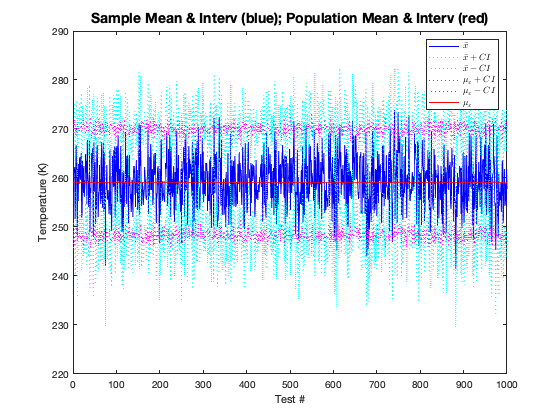


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%

% create a single line that will represent the population mean

muline = zeros([1,number_of_tests]) + mu_d; 

% Plot the max and min limits of each test (cyan) and "true" population
% mean (red), and the sample population (blue)

figure('Name','Plot of Confidence Limits and Population Mean', ...
                 'Color','white'); % makes a white background, not grey
             
plot(test_number, mean_archive,         'b',  ...
     test_number, lo_archive,           'c:',  ...
     test_number, hi_archive,           'c:',  ...
     test_number, muline-conf_archive,  'm:',  ...
     test_number, muline+conf_archive,  'm:',  ...
     test_number, muline,               'r'   );
 
xlabel('Test #');              % we'll dock for no axis labels!
ylabel(strcat(long_name, ...   % we'll still dock for no axis labels!
              ' (',      ...
              units,     ...
              ')'            ));                 
                                            
title('Sample Mean & Interv (blue); Population Mean & Interv (red)', ...
      'FontSize',14);                % titles are handy too...

% ok here my need to be OCD got the best of me.
%  legends are nice.  But to do symbols in matlab
%  output you need to use LaTeX which is a powerful
%  editor whose files look great when you print them
%  but when you type them, everything looks like it 
%  did in the ancient days before WYSIWYG graphical
%  editors.
%
% I use a online resource to convert visual equations
%   into "LaTeXeese."
%
% here is one here. https://www.codecogs.com/latex/eqneditor.php

latex_legend =  legend("$\bar{x}$", ...
         "$\bar{x} + CI$",...
         "$\bar{x} - CI$",...
         "$\mu_{x} + CI$",...
         "$\mu_{x} - CI$",...
         "$\mu_{x}$");
     
 set(latex_legend,'interpreter','Latex');



%
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



We should see most of our values of $\bar{x}$ (our guesses for $\mu_x$) to be inside the magenta lines.

## Revisiting How the T-Distribution can be Seen in Our Data

Finally, let's look at those t-statistics and what kind of shape the all make (since that's what's making the histogram).  

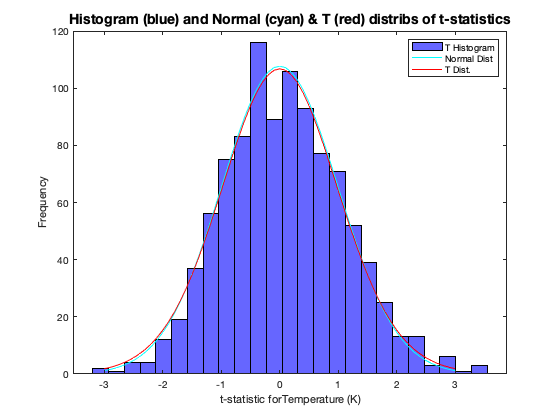

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%

figure('Name','Histogram of T-Statistic', ...
                 'Color','white'); % makes a white batckground, not grey
             

% this not only plots a histogram but create a variable, 
%     "histogram_output" that archives information used
%     to make the plot
histogram_output = histogram(t_archive, 25, ...  % generate histogram w/ 25bins
                              'FaceColor','b'); % and make it blue


xlabel(strcat('t-statistic for ', ...
               long_name, ...       % we'll dock for no axis labels!
              ' (',      ...
              units,     ...
              ')'            ));                 
ylabel('Frequency');               % we'll still dock for no axis labels!
title('Histogram (blue) and Normal (cyan) & T (red) distribs of t-statistics', ...
    'FontSize',14);                % titles are handy too...

% set things up to overlay the plot
hold on % don't make a new plot... 

bin_width = histogram_output.BinWidth; % binwidth pulled 
                      % from the histogram function output

ttpdf=  tpdf(range_of_t_or_z, n_sample_size-1) * ...
        (number_of_tests*bin_width); 
    
ntpdf=  normpdf(range_of_t_or_z) * (number_of_tests*bin_width);
    
        
plot(range_of_t_or_z, ntpdf, 'c');
plot(range_of_t_or_z, ttpdf, 'r');
legend('T Histogram', ...
       'Normal Dist', ...
       'T Dist.')  ...

hold off % ok _now_ you can make a new plot... 

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

So here we can see that indeed we are making a distribution that is similar to the normal distribution.  

## A Note on "Prediction Limits"

As a "second" "finally" I should touch on the idea of prediction limits.

I am personally not fond of them since they are not the safest pair of lawndarts throw around the numerical yard.  Unfortunately they are often lumped in with confidence limits in both analyses and graphics products.

"Confidence limits" determine the uncertainty in estimating the mean leveraging what we know about the central limit theroem.

"Prediction limtis" get a little braver.  Rather than estimate the certainty of capturing of the population mean, $\mu_x$, with your sample statistics, the prediction limit tries to identify certainty of capturing any new value.  As you know looking at the various distributions of properties, not all raw data conforms to a pretty symetric normal distribution.  And this could be a scary proposition.  

This the closer data is to a normal distribution the safe you may be using prediction limits.

The formula for prediction limits are similar to the confidence limits but with an additional term.


$$x_{\textrm{new}} \simeq \bar{x} \pm s_x \sqrt{1+\frac{1}{n}}\;\;t_{\left(\alpha /2,\textrm{df}\right)} \;$$


This creates a much "fatter" range of error as you should expect.

This for a 95% confidence of capturing the population mean or any new single value based on knowledge of a sample mean and a sample standard deviation based for a 30 of samples...

...using our 626th experiment [for chuckles] the range on the population mean would be...

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
%  Fast Crunch on the confidence & prediction limits for the 
%     "Experiment 626."
%
    i = 626;
    
    conf  =  t_statistic * stdv_archive(i) / sqrt(n_sample_size);
    
    hi_conf   =  mean_archive(i) + conf;
    lo_conf   =  mean_archive(i) - conf;

    pred  =  t_statistic * stdv_archive(i) * sqrt(1 + 1/n_sample_size);

    hi_pred   =  mean_archive(i) + pred;
    lo_pred   =  mean_archive(i) - pred;
        
    fprintf([' Confidence Limit Range %7.2f to %7.2f\n',  ...
             ' Prediction Limit Range %7.2f to %7.2f\n'], ...
             lo_conf,hi_conf, ...
             lo_pred,hi_pred);

 Confidence Limit Range  254.91 to  278.24
 Prediction Limit Range  201.63 to  331.52


%    
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

But as mentioned earlier, the effectiveness of this hinges on having a normal distribution for your data.  And here we demonstrate with the same test as we did above but without the each "experiment's" output.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Prediction Limit Exclusion Test
%

x_archive    = zeros([1,number_of_tests]); % we'll each test's sample mean here
pred_archive = zeros([1,number_of_tests]); % we'll each test's sample mean here

n_within  = 0;  %
n_outside = 0;  % counter of values outside of confidence limit

n_too_high = 0;  % counter of values outside of confidence limit
n_too_low  = 0;


%  Loop on i from 1 to number of tests.

for i = 1:number_of_tests

    % let's just take the data from the earlier cases
    
    % each time we get our new value from the mystery bag
    new_x = randsample(data,1); 
                                               
    % calculate mean, standard dev and confidence interv. of sample
    x_bar = mean_archive(i);
    s     = stdv_archive(i);
    pred  = t_statistic * s * sqrt(1 + 1/n_sample_size);
    
    
    hi =   x_bar + pred;  % high limit to pred of new(x)
    lo =   x_bar - pred;  % low  limit to pred of new(x)

    % store key value for future use
    
    x_archive(i)    = new_x;
    pred_archive(i) = pred;
    lo_archive(i)   = lo;
    hi_archive(i)   = hi;
    

    % Checks to see if you are between the confidence limts.

    if ((lo < new_x) && (new_x < hi))  
        % "Sometimes You Get the Bear..."
        %     HUZZAH!  Your population new value is captured between the 
        %     prediction limits
        n_within = n_within + 1;
    else
        % "...Sometimes The Bear Gets You..."
        %     BAD THING!  Your population new value is not captured between the 
        %     prediction limits
        n_outside = n_outside + 1;
        if (new_x < lo)  
           n_too_low = n_too_low + 1;
        end
        if (new_x > hi)  
           n_too_high = n_too_high + 1;
        end
        
    end

end


% And our results

fprintf(['=============================================================\n',  ...
         '              mean sample mean = %7.3f\n',    ...
         '                   mean new x  = %7.3f\n',    ...
         'mean sample standard deviation = %7.3f\n',    ...
         '      mean prediction interval = %7.3f\n',    ...
         '      mean hi prediction value = %7.3f\n',    ...
         '      mean lo prediction value = %7.3f\n',    ...
         '                                       \n',   ...
         '               percent too low = %6.2f%%\n',  ...
         '     percent within prediction = %6.2f%%\n',  ...
         '              percent too high = %6.2f%%\n',  ...
         '   percent too high or too low = %6.2f%%\n',  ...
         '-------------------------------------------------------------\n',  ...
         '                         total = %6.2f%%\n',  ...
         '=============================================================\n'], ...
        mean(mean_archive),              ...
        mean(x_archive),                 ...
        mean(stdv_archive),              ...
        mean(pred_archive),              ...
        mean(lo_archive),                ...
        mean(hi_archive),                ...
        n_too_low*100/number_of_tests,   ...
        n_within*100/number_of_tests,    ...
        n_too_high*100/number_of_tests,  ...
        n_outside*100/number_of_tests,   ...
        (n_too_low+n_within+n_too_high)*100/number_of_tests )

              mean sample mean = 259.261
                   mean new x  = 258.691
mean sample standard deviation =  29.001
      mean prediction interval =  60.295
      mean hi prediction value = 198.966
      mean lo prediction value = 319.556
                                       
               percent too low =   2.20%
     percent within prediction =  97.70%
              percent too high =   0.10%
   percent too high or too low =   2.30%
-------------------------------------------------------------
                         total = 100.00%


%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

And graphically... 

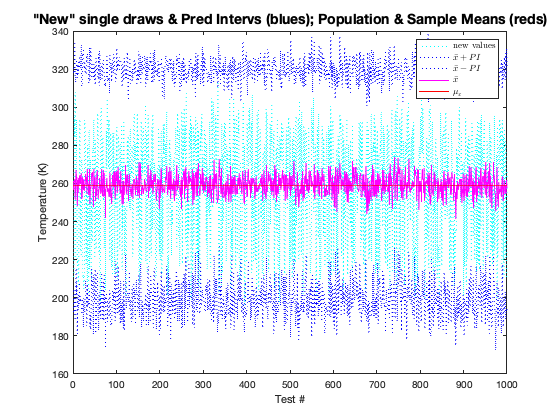

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Creating a plot to show prediction limits

% Plot the max and min limits of each test (cyan) and "true" population
% mean (red), and the sample population (blue)

figure('Name','Plot of Prediction Limits', ...
                 'Color','white'); % makes a white background, not grey
             
plot(test_number, x_archive,            'c:',  ...
     test_number, lo_archive,           'b:',  ...
     test_number, hi_archive,           'b:',  ...
     test_number, mean_archive,         "m", ...
     test_number, muline,               'r'   );
xlabel('Test #');              % we'll dock for no axis labels!
ylabel(strcat(long_name, ...   % we'll still dock for no axis labels!
              ' (',      ...
              units,     ...
              ')'            ));                                                        
title('"New" single draws & Pred Intervs (blues); Population & Sample Means (reds)', ...
    'FontSize',14);                % titles are handy too...
% once again, I am having to "LaTeX"

 latex_legend = legend("new values",       ...
                       "$\bar{x} + PI $",  ...
                       "$\bar{x} - PI $",  ...
                       "$\bar{x}$",        ...
                       "$\mu_{x}$");
                   
 set(latex_legend,'interpreter','Latex');


%
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


So in this case we were able to capture more than 95% of the new single values from the population.  If you look at the original histogram of the full "population" dataset vs the plotted distribution curve at the top of this script, you'll notice that our population is mostly well inside the normal distribution curve. Other parameters in the forecast model dataset provided here may give you different results.  